start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


## Choose Water Network

d=epanet('Hanoi.inp');

EPANET version {20200} loaded (EMT version {v2.2.1}).
Loading File "Hanoi.inp"...
Input File "Hanoi.inp" loaded successfully.



nj = double(d.getNodeJunctionCount);
nn = double(d.getNodeCount);
reservInd = d.getNodeReservoirIndex;


## Calculate Sensitivity matrix

 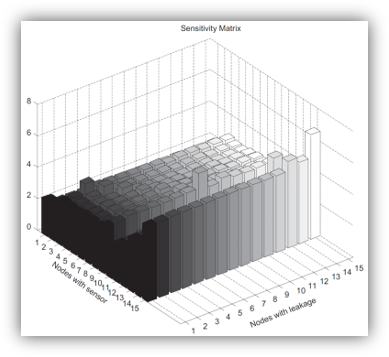

Calculate healthy states in extended time simulation:

d.setTimeSimulationDuration(24*60*60) % greater weight to low demand hours
d.setTimePatternStart(0) %in seconds
allParameters=d.getComputedTimeSeries;
P0 = allParameters.Pressure';
P0(d.getNodeReservoirIndex,:)=[];
Dem0 = allParameters.Demand';
simSteps = size(P0,2);


%% Create Augmented-time Sensitivity Matrix

%%% Simulate all leakages and get all scenarios pressures

leak_mag_desir=mean(mean(Dem0(Dem0>0)));
mean_pressure = mean(mean(P0(P0>0)));
leak_emit = leak_mag_desir/sqrt(mean_pressure);
emit0=d.getNodeEmitterCoeff;
S = zeros(nj,nj);
for leak=1:nj
    clc
    disp('Calculating Sensitivity Matrix...')
    disp(['Simulating leakage ',num2str(leak),' out of ',num2str(nj)])
    emit=zeros(size(emit0));
    emit(leak)=leak_emit; % set emitter coefficient (leakage) value
    d.setNodeEmitterCoeff(emit);
    allParameters=d.getComputedTimeSeries;
    P = allParameters.Pressure';
    P(d.getNodeReservoirIndex,:)=[];
    Dem = allParameters.Demand';
    leak_mag = Dem(leak,:)-Dem0(leak,:);
    Stmp=(P-P0)./(leak_mag);
    rmax = max(abs(Stmp),[],1);
    Stmp = abs(Stmp)./rmax;
    S(:,leak) = max(Stmp')'; % --> main difference in max-min Sensitivity!!!
end

Calculating Sensitivity Matrix...


Simulating leakage 1 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 2 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 3 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 4 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 5 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 6 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 7 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 8 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 9 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 10 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 11 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 12 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 13 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 14 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 15 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 16 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 17 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 18 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 19 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 20 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 21 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 22 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 23 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 24 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 25 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 26 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 27 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 28 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 29 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 30 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 31 out of 31


## Place sensors 

Select number of sensors to be installed:

sensors_num=4;

Define existing sensors in the network:

exist_sens_ind=[]; % define existing sensors in the network
% exist_sens_ind=d.getNodeIndex({'14','63','114','399','572','302','662'});

Solve using GA: Maximize the minimum sensitivity of all sensors to any leakage

[res,fvalSenTr] = SolveEnum2GA(S,nj,sensors_num,exist_sens_ind)

cost =       0.78741


cost =       0.78451


cost =       0.78923


cost =       0.71906


cost =       0.69041


cost =       0.78041


cost =       0.68912


cost =       0.69322


cost =       0.78325


cost =       0.61363


cost =       0.77108


cost =       0.63601


cost =       0.77276


cost =       0.77576


cost =       0.77206


cost =       0.77817


cost =       0.64053


cost =        0.7722


cost =       0.77528


cost =       0.77961


cost =       0.64173


cost =       0.58798


cost =       0.64496


cost =       0.77722


cost =       0.77013


cost =       0.58672


cost =       0.77423


cost =       0.77734


cost =       0.77977


cost =       0.64148


cost =        0.6436


cost =       0.77276


cost =       0.78121


cost =       0.64804


cost =       0.50676


cost =       0.77927


cost =       0.78682


cost =       0.77862


cost =       0.78002


cost =       0.77927


cost =       0.78246


cost =       0.64162


cost =       0.58788


cost =       0.64486


cost =       0.64788


cost =       0.77241


cost =       0.77637


cost =       0.78263


cost =       0.77367


cost =       0.77839


cost =       0.78161


cost =       0.63229


cost =       0.65838


cost =       0.59065


cost =       0.64977


cost =       0.77571


cost =       0.78005


cost =       0.67138


cost =        0.7799


cost =        0.7751


cost =       0.77915


cost =       0.78234


cost =       0.64474


cost =       0.64777


cost =       0.78252


cost =       0.71059


cost =       0.78156


cost =       0.77674


cost =       0.78087


cost =         0.784


cost =       0.63051


cost =       0.64878


cost =       0.64788


cost =       0.65505


cost =       0.78423


cost =       0.71233


cost =        0.7822


cost =       0.78106


cost =       0.78597


cost =       0.78542


cost =       0.78628


cost =       0.77994


cost =       0.63194


cost =        0.6463


cost =       0.65063


cost =       0.77311


cost =       0.77957


cost =       0.77947


cost =       0.63327


cost =       0.77737


cost =       0.57667


cost =         0.775


cost =       0.77703


cost =       0.77994


cost =       0.78194


cost =       0.77919


cost =       0.77869


cost =       0.78238


cost =        0.6289


cost =       0.64154


cost =       0.64478


cost =       0.77629


cost =       0.77953


cost =       0.78255


cost =       0.77456


cost =       0.78071


cost =       0.58892


cost =       0.77746


cost =       0.77854


cost =       0.78158


cost =       0.78088


cost =       0.78402


cost =        0.6488


cost =       0.64789


cost =       0.77798


cost =       0.78117


cost =       0.71235


cost =        0.7773


cost =       0.78221


cost =       0.77984


cost =       0.78107


cost =       0.78599


cost =       0.78544


cost =       0.71056


cost =       0.78352


cost =       0.78297


cost =       0.78596


cost =       0.64984


cost =       0.67134


cost =       0.77582


cost =       0.78311


cost =       0.78642


cost =       0.71452


cost =       0.78391


cost =       0.70818


cost =       0.78106


cost =       0.78598


cost =       0.78543


cost =       0.71055


cost =       0.78186


cost =       0.78278


cost =       0.78764


cost =       0.78715


cost =        0.7123


cost =       0.84605


cost =       0.78361


cost =       0.71233


cost =       0.78262


cost =       0.72046


cost =       0.68845


cost =       0.78839


cost =        0.7742


cost =       0.77623


cost =       0.77754


cost =       0.77517


cost =       0.77873


cost =       0.64886


cost =       0.78228


cost =       0.59098


cost =       0.78333


cost =       0.78437


cost =       0.78631


cost =       0.78278


cost =       0.78803


cost =       0.84605


cost =       0.78741


cost =        0.7188


cost =       0.68775


cost =       0.72792


cost =       0.78432


cost =       0.78071


cost =       0.78473


cost =       0.73481


cost =       0.73231


cost =       0.78252


cost =       0.68908


cost =       0.68379


cost =       0.78357


cost =       0.60856


cost =       0.60809


cost =       0.61363


cost =       0.77452


cost =       0.77536


cost =       0.77576


cost =       0.77598


cost =       0.77506


cost =       0.77817


cost =       0.62878


cost =       0.64167


cost =       0.64486


cost =       0.77214


cost =       0.77134


cost =       0.77177


cost =       0.77237


cost =       0.77642


cost =       0.77961


cost =       0.58798


cost =       0.77478


cost =       0.58672


cost =        0.6301


cost =       0.77734


cost =       0.77566


cost =       0.77977


cost =       0.62734


cost =       0.62864


cost =       0.64889


cost =       0.64793


cost =       0.77421


cost =       0.77808


cost =       0.78121


cost =        0.6552


cost =       0.50676


cost =       0.77602


cost =       0.69781


cost =       0.77905


cost =       0.78002


cost =       0.77522


cost =       0.77927


cost =       0.78246


cost =       0.58788


cost =       0.64486


cost =       0.78263


cost =       0.78442


cost =       0.70617


cost =       0.62964


cost =       0.77263


cost =         0.776


cost =       0.77502


cost =       0.77839


cost =       0.78161


cost =        0.6311


cost =       0.63039


cost =       0.64544


cost =       0.63053


cost =       0.63229


cost =       0.59065


cost =       0.77554


cost =       0.77871


cost =        0.7761


cost =       0.78305


cost =       0.65843


cost =       0.77359


cost =       0.59074


cost =       0.77581


cost =       0.77781


cost =       0.77851


cost =        0.7799


cost =        0.7819


cost =       0.77551


cost =       0.77865


cost =       0.64151


cost =       0.64474


cost =       0.77949


cost =       0.78252


cost =       0.71059


cost =       0.78895


cost =       0.78015


cost =       0.78156


cost =       0.62877


cost =       0.64878


cost =       0.64788


cost =       0.77393


cost =       0.77797


cost =       0.70646


cost =       0.78106


cost =       0.78597


cost =       0.78542


cost =       0.71055


cost =       0.78628


cost =       0.78005


cost =       0.77793


cost =       0.77803


cost =        0.7826


cost =        0.7798


cost =       0.62992


cost =       0.63122


cost =       0.63136


cost =       0.65063


cost =       0.77639


cost =       0.78391


cost =       0.63151


cost =       0.65073


cost =       0.67727


cost =       0.77396


cost =       0.57711


cost =       0.57667


cost =       0.63952


cost =       0.77897


cost =       0.77919


cost =       0.77869


cost =       0.78238


cost =        0.6289


cost =       0.64154


cost =       0.64478


cost =       0.78255


cost =       0.58892


cost =       0.77716


cost =       0.78088


cost =       0.78402


cost =       0.63052


cost =       0.65506


cost =       0.78425


cost =       0.78107


cost =       0.78599


cost =       0.78544


cost =       0.71056


cost =        0.7823


cost =       0.77792


cost =       0.77512


cost =       0.78352


cost =       0.63239


cost =        0.6584


cost =       0.64984


cost =       0.77621


cost =       0.78007


cost =       0.78391


cost =       0.78335


cost =       0.78598


cost =       0.71055


cost =       0.78629


cost =       0.78278


cost =       0.79454


cost =       0.78764


cost =       0.78715


cost =        0.7123


cost =       0.84605


cost =       0.78764


cost =       0.71379


cost =       0.78908


cost =        0.6894


cost =       0.78079


cost =       0.78002


cost =       0.78075


cost =       0.62885


cost =       0.77973


cost =       0.78022


cost =       0.59098


cost =       0.67132


cost =        0.7145


cost =       0.77898


cost =       0.77956


cost =       0.83752


cost =       0.78336


cost =       0.78386


cost =       0.83603


cost =       0.78098


cost =       0.78445


cost =       0.79021


cost =       0.84833


cost =       0.78722


cost =       0.78751


cost =       0.78603


cost =       0.71795


cost =        0.7188


cost =       0.71813


cost =       0.71938


cost =        0.7844


cost =       0.78461


cost =       0.78313


cost =        0.7848


cost =       0.71906


cost =       0.71949


cost =       0.69456


cost =       0.78182


cost =       0.77956


cost =       0.68943


cost =       0.69086


cost =       0.60827


cost =       0.60849


cost =       0.61148


cost =       0.77391


cost =       0.62642


cost =       0.77276


cost =       0.77594


cost =       0.77255


cost =       0.56331


cost =       0.56281


cost =       0.64053


cost =       0.62895


cost =       0.77528


cost =       0.77277


cost =       0.62909


cost =       0.64173


cost =       0.64496


cost =       0.64799


cost =       0.77437


cost =       0.45617


cost =       0.69634


cost =       0.77807


cost =       0.77992


cost =       0.62933


cost =       0.56427


cost =       0.63035


cost =        0.6436


cost =       0.77071


cost =       0.58945


cost =       0.64804


cost =       0.77497


cost =        0.7726


cost =       0.77165


cost =       0.77518


cost =        0.5064


cost =       0.78002


cost =       0.78202


cost =       0.77522


cost =       0.77927


cost =       0.62898


cost =       0.64162


cost =       0.64486


cost =       0.77637


cost =       0.78078


cost =       0.77903


cost =       0.62885


cost =       0.62805


cost =       0.77308


cost =       0.53151


cost =        0.5307


cost =         0.773


cost =       0.77554


cost =       0.62883


cost =         0.781


cost =       0.77927


cost =       0.78161


cost =       0.62989


cost =       0.63229


cost =       0.65838


cost =       0.78005


cost =       0.78305


cost =       0.63243


cost =       0.65843


cost =       0.64987


cost =       0.77699


cost =       0.77315


cost =       0.78028


cost =       0.55887


cost =       0.63475


cost =       0.77989


cost =       0.77639


cost =       0.77915


cost =       0.78234


cost =       0.64777


cost =       0.77229


cost =       0.77576


cost =       0.78058


cost =       0.77674


cost =       0.78087


cost =         0.784


cost =       0.64788


cost =       0.78423


cost =       0.71233


cost =       0.77732


cost =       0.78164


cost =       0.78597


cost =       0.78542


cost =       0.71055


cost =       0.78231


cost =       0.78136


cost =       0.77513


cost =       0.78094


cost =       0.77994


cost =       0.77839


cost =       0.63296


cost =        0.6463


cost =       0.77536


cost =       0.77639


cost =       0.65073


cost =       0.57667


cost =       0.59155


cost =       0.78167


cost =       0.77842


cost =       0.77548


cost =       0.63952


cost =       0.77854


cost =       0.77994


cost =       0.64154


cost =        0.5878


cost =       0.64478


cost =        0.6478


cost =       0.77233


cost =       0.77629


cost =       0.77953


cost =       0.71063


cost =       0.77746


cost =       0.78158


cost =        0.6488


cost =       0.64789


cost =       0.78117


cost =       0.71235


cost =       0.77893


cost =       0.78023


cost =       0.78107


cost =       0.78599


cost =       0.78544


cost =       0.71056


cost =       0.78135


cost =       0.77802


cost =       0.77721


cost =       0.83711


cost =       0.77933


cost =       0.77863


cost =       0.78297


cost =       0.78596


cost =       0.64984


cost =       0.77582


cost =       0.78642


cost =       0.78598


cost =       0.78543


cost =       0.71055


cost =       0.78764


cost =       0.78715


cost =       0.84605


cost =        0.5893


cost =       0.84715


cost =       0.79007


cost =       0.78434


cost =       0.78397


cost =       0.61115


cost =       0.77921


cost =       0.78164


cost =       0.64192


cost =        0.7864


cost =       0.65929


cost =       0.78471


cost =       0.78335


cost =       0.71884


cost =       0.71901


cost =       0.72792


cost =       0.78432


cost =       0.78346


cost =       0.78923


cost =       0.68839


cost =       0.72009


cost =       0.69424


cost =       0.73481


cost =       0.73231


cost =       0.68908


cost =       0.61061


cost =       0.61291


cost =       0.77035


cost =       0.62945


cost =        0.7737


cost =       0.77817


cost =       0.62706


cost =        0.6272


cost =       0.62895


cost =       0.64167


cost =       0.64486


cost =       0.77642


cost =       0.77592


cost =       0.77961


cost =       0.77098


cost =       0.77722


cost =         0.454


cost =       0.77316


cost =       0.78054


cost =       0.70879


cost =       0.64432


cost =       0.62847


cost =       0.64799


cost =       0.77723


cost =       0.77977


cost =       0.62814


cost =       0.56477


cost =       0.62864


cost =       0.64793


cost =       0.77808


cost =       0.78121


cost =       0.64894


cost =       0.58945


cost =        0.6552


cost =       0.77156


cost =       0.50676


cost =       0.77462


cost =       0.58819


cost =       0.77608


cost =       0.77927


cost =       0.77877


cost =       0.78246


cost =       0.62725


cost =       0.78263


cost =       0.79252


cost =       0.77823


cost =       0.77806


cost =       0.77723


cost =       0.56541


cost =       0.62935


cost =       0.77442


cost =       0.77362


cost =       0.77492


cost =        0.7762


cost =       0.77228


cost =       0.77182


cost =       0.76902


cost =       0.77992


cost =       0.77897


cost =       0.62717


cost =       0.77274


cost =        0.7775


cost =       0.77657


cost =       0.63212


cost =       0.64544


cost =       0.63053


cost =       0.77466


cost =       0.77871


cost =       0.77512


cost =       0.56228


cost =       0.77716


cost =       0.77379


cost =       0.77639


cost =        0.7799


cost =       0.62713


cost =       0.62887


cost =       0.64151


cost =       0.64474


cost =        0.7727


cost =       0.77609


cost =       0.77949


cost =       0.71059


cost =       0.77576


cost =       0.78011


cost =        0.7776


cost =       0.78156


cost =       0.77714


cost =       0.78087


cost =         0.784


cost =       0.62877


cost =       0.63051


cost =       0.64878


cost =       0.64788


cost =       0.65505


cost =       0.77797


cost =       0.78115


cost =        0.7822


cost =       0.70646


cost =       0.78106


cost =       0.78597


cost =       0.71055


cost =       0.78628


cost =       0.62956


cost =       0.77722


cost =       0.77892


cost =        0.7826


cost =        0.7798


cost =       0.77826


cost =       0.78247


cost =       0.62992


cost =       0.57914


cost =       0.63122


cost =       0.63136


cost =       0.65928


cost =       0.65063


cost =       0.78096


cost =       0.78391


cost =       0.63327


cost =       0.65934


cost =       0.67727


cost =        0.7778


cost =       0.57667


cost =         0.776


cost =       0.77584


cost =       0.77514


cost =       0.77919


cost =       0.78238


cost =       0.62717


cost =       0.64478


cost =        0.6478


cost =       0.77953


cost =       0.78255


cost =       0.71063


cost =       0.77579


cost =       0.78088


cost =       0.78402


cost =       0.63052


cost =       0.65506


cost =       0.78117


cost =       0.78425


cost =       0.78544


cost =       0.77792


cost =       0.62955


cost =       0.77512


cost =       0.78203


cost =       0.78352


cost =        0.6584


cost =       0.77582


cost =       0.78007


cost =       0.70818


cost =       0.78106


cost =       0.78598


cost =       0.78543


cost =       0.71055


cost =       0.78629


cost =       0.78186


cost =       0.78278


cost =       0.78764


cost =       0.78803


cost =       0.84605


cost =        0.5879


cost =       0.78095


cost =       0.62957


cost =       0.67132


cost =       0.78309


cost =       0.78021


cost =       0.78801


cost =       0.79624


cost =        0.7188


cost =        0.6881


cost =       0.77966


cost =       0.78551


cost =       0.78923


cost =       0.69041


cost =       0.72009


cost =       0.72798


cost =       0.78252


cost =       0.78084


cost =       0.68798


cost =       0.78626


cost =       0.69328


cost =       0.60856


cost =        0.7719


cost =       0.77484


cost =       0.77671


cost =       0.77623


cost =       0.62657


cost =       0.62776


cost =       0.62878


cost =        0.6272


cost =       0.76925


cost =       0.77528


cost =       0.62735


cost =       0.62909


cost =       0.64173


cost =       0.64496


cost =        0.7735


cost =       0.77478


cost =        0.7701


cost =       0.47065


cost =       0.77113


cost =       0.70516


cost =       0.77372


cost =       0.45617


cost =       0.77613


cost =       0.77977


cost =       0.63035


cost =        0.6436


cost =       0.63052


cost =       0.58906


cost =       0.77687


cost =       0.77707


cost =       0.62893


cost =       0.63066


cost =       0.64894


cost =       0.77227


cost =       0.77458


cost =        0.5072


cost =       0.76919


cost =       0.77827


cost =       0.77752


cost =       0.77711


cost =       0.77905


cost =       0.78002


cost =       0.77927


cost =       0.77877


cost =       0.78246


cost =       0.62898


cost =       0.64486


cost =       0.64788


cost =       0.77637


cost =       0.77961


cost =       0.78263


cost =       0.71071


cost =        0.7759


cost =       0.62885


cost =       0.62949


cost =       0.58969


cost =       0.62964


cost =       0.77606


cost =       0.62514


cost =         0.773


cost =       0.77785


cost =       0.77554


cost =        0.7772


cost =       0.78093


cost =       0.62883


cost =        0.7744


cost =       0.77756


cost =       0.77512


cost =       0.78161


cost =        0.6311


cost =       0.64544


cost =       0.59033


cost =       0.65838


cost =       0.64977


cost =       0.78305


cost =       0.65843


cost =       0.64987


cost =       0.67138


cost =       0.77702


cost =       0.77709


cost =       0.55843


cost =       0.59074


cost =       0.70857


cost =       0.77296


cost =       0.77781


cost =       0.77894


cost =       0.77915


cost =       0.77865


cost =       0.78234


cost =       0.64474


cost =       0.77625


cost =       0.78252


cost =       0.70994


cost =       0.78087


cost =         0.784


cost =       0.64878


cost =       0.65505


cost =       0.78423


cost =       0.78106


cost =       0.78597


cost =       0.78542


cost =       0.78628


cost =       0.62956


cost =       0.78094


cost =       0.77924


cost =       0.78247


cost =       0.63072


cost =       0.63194


cost =        0.6463


cost =       0.77679


cost =       0.77639


cost =       0.77957


cost =       0.77655


cost =       0.78096


cost =       0.65934


cost =       0.77698


cost =       0.70902


cost =       0.78173


cost =       0.77992


cost =       0.77584


cost =       0.77785


cost =       0.64478


cost =       0.77274


cost =       0.77953


cost =       0.71063


cost =       0.70497


cost =       0.78016


cost =       0.78158


cost =       0.78088


cost =        0.6488


cost =       0.64789


cost =       0.77395


cost =       0.77798


cost =       0.78117


cost =       0.78107


cost =       0.78599


cost =       0.78544


cost =       0.71056


cost =        0.7863


cost =       0.77721


cost =       0.78093


cost =       0.78352


cost =       0.78596


cost =       0.64984


cost =       0.67134


cost =       0.78007


cost =       0.78642


cost =       0.71452


cost =       0.77823


cost =       0.78598


cost =       0.78543


cost =       0.71055


cost =       0.78764


cost =       0.78715


cost =       0.84605


cost =       0.64902


cost =       0.78276


cost =       0.78519


cost =       0.78194


cost =        0.5879


cost =       0.84415


cost =       0.70816


cost =       0.65068


cost =       0.77986


cost =        0.7123


cost =       0.78839


cost =       0.71766


cost =        0.6868


cost =       0.69002


cost =       0.71998


cost =       0.72792


cost =       0.71895


cost =       0.71819


cost =       0.71906


cost =       0.68789


cost =       0.71949


cost =       0.72025


cost =       0.73481


cost =       0.68798


cost =       0.77967


cost =        0.7773


cost =        0.6084


cost =       0.62504


cost =        0.7657


cost =       0.69432


cost =       0.77693


cost =       0.77594


cost =       0.77576


cost =       0.77467


cost =       0.77817


cost =       0.56532


cost =       0.62706


cost =       0.64167


cost =       0.58759


cost =       0.64486


cost =       0.77118


cost =       0.77642


cost =       0.77961


cost =       0.64799


cost =       0.77491


cost =       0.77396


cost =       0.45356


cost =       0.77455


cost =       0.77521


cost =        0.6397


cost =       0.77723


cost =       0.77977


cost =       0.62864


cost =       0.63052


cost =       0.64889


cost =       0.64793


cost =       0.77378


cost =       0.77687


cost =       0.77808


cost =       0.78121


cost =       0.77458


cost =       0.50676


cost =       0.77884


cost =       0.63157


cost =       0.70302


cost =       0.77592


cost =       0.78246


cost =       0.64486


cost =       0.64788


cost =       0.77961


cost =       0.77587


cost =       0.77868


cost =       0.77777


cost =       0.62805


cost =       0.62935


cost =        0.7762


cost =       0.77367


cost =       0.77526


cost =       0.77182


cost =       0.77897


cost =       0.62717


cost =       0.77502


cost =         0.781


cost =       0.77852


cost =       0.78161


cost =       0.63039


cost =       0.63212


cost =       0.65838


cost =       0.64977


cost =       0.77482


cost =       0.77871


cost =       0.67138


cost =       0.77702


cost =       0.77784


cost =       0.55938


cost =       0.77034


cost =       0.55807


cost =       0.69627


cost =       0.64574


cost =       0.70291


cost =       0.78187


cost =       0.77596


cost =        0.7799


cost =       0.78234


cost =       0.62713


cost =       0.62887


cost =       0.64151


cost =       0.64474


cost =       0.64777


cost =       0.77229


cost =       0.77625


cost =       0.77609


cost =       0.78067


cost =       0.69612


cost =       0.77792


cost =         0.784


cost =       0.64788


cost =       0.65505


cost =       0.78115


cost =       0.71233


cost =        0.7782


cost =       0.78106


cost =       0.78597


cost =       0.78542


cost =       0.71055


cost =         0.836


cost =       0.77793


cost =       0.77663


cost =       0.65928


cost =       0.77957


cost =       0.77947


cost =       0.78391


cost =       0.63151


cost =       0.77467


cost =       0.57762


cost =       0.59155


cost =       0.70021


cost =       0.77744


cost =       0.77703


cost =       0.77994


cost =       0.77919


cost =       0.78238


cost =       0.62717


cost =       0.64154


cost =        0.6478


cost =       0.77953


cost =       0.78255


cost =       0.77761


cost =       0.78158


cost =       0.77676


cost =       0.78402


cost =       0.64789


cost =       0.77436


cost =       0.77798


cost =       0.78425


cost =       0.71235


cost =       0.78221


cost =       0.78599


cost =       0.78544


cost =        0.7863


cost =       0.77933


cost =       0.78352


cost =       0.78297


cost =       0.78596


cost =       0.67134


cost =       0.78311


cost =       0.70853


cost =       0.78023


cost =       0.78106


cost =       0.78598


cost =       0.78543


cost =       0.78629


cost =       0.78278


cost =       0.78764


cost =       0.78715


cost =        0.7123


cost =       0.78803


cost =       0.84605


cost =       0.77935


cost =        0.7801


cost =       0.78214


cost =       0.78054


cost =       0.61325


cost =       0.78204


cost =       0.62727


cost =        0.5879


cost =       0.64488


cost =       0.78409


cost =       0.65513


cost =       0.77991


cost =       0.77724


cost =       0.78594


cost =       0.67722


cost =        0.8441


cost =       0.78764


cost =       0.83924


cost =       0.71767


cost =       0.71884


cost =       0.71938


cost =       0.72792


cost =       0.69414


cost =       0.78537


cost =       0.78085


cost =       0.69041


cost =       0.72009


cost =       0.72798


cost =       0.73481


cost =        0.6881


cost =       0.68912


cost =       0.69651


cost =       0.69952


cost =        0.7767


cost =       0.60841


cost =       0.61494


cost =       0.77389


cost =       0.63473


cost =       0.77467


cost =       0.77549


cost =       0.62576


cost =       0.56532


cost =       0.62706


cost =       0.64053


cost =        0.6272


cost =       0.62895


cost =       0.64486


cost =       0.77528


cost =       0.77642


cost =       0.64496


cost =       0.64799


cost =       0.77802


cost =       0.45356


cost =       0.58768


cost =       0.77372


cost =       0.69432


cost =       0.56427


cost =        0.6436


cost =       0.64889


cost =       0.58906


cost =       0.78121


cost =       0.64894


cost =       0.58945


cost =       0.77227


cost =       0.51061


cost =       0.77376


cost =       0.50937


cost =       0.77827


cost =       0.77385


cost =       0.77747


cost =       0.78002


cost =       0.77632


cost =       0.77927


cost =       0.78246


cost =       0.62725


cost =       0.64162


cost =       0.64486


cost =       0.64788


cost =       0.78263


cost =       0.71071


cost =       0.78907


cost =       0.70505


cost =       0.78067


cost =       0.62885


cost =       0.62949


cost =       0.62964


cost =       0.76902


cost =         0.772


cost =       0.77417


cost =         0.776


cost =       0.77554


cost =       0.62717


cost =       0.77502


cost =       0.78063


cost =       0.77738


cost =        0.7791


cost =       0.77742


cost =       0.78161


cost =       0.63053


cost =       0.77452


cost =       0.78305


cost =       0.55843


cost =       0.58694


cost =       0.59074


cost =        0.5576


cost =       0.77505


cost =       0.77596


cost =       0.77851


cost =        0.7799


cost =        0.7751


cost =       0.77915


cost =       0.78234


cost =       0.64474


cost =       0.77229


cost =       0.77625


cost =       0.78252


cost =       0.77745


cost =       0.78156


cost =       0.78087


cost =         0.784


cost =       0.64878


cost =       0.77434


cost =       0.77393


cost =       0.78115


cost =       0.78423


cost =       0.70646


cost =       0.70852


cost =        0.7099


cost =       0.78022


cost =       0.78106


cost =       0.78597


cost =       0.78542


cost =       0.78136


cost =       0.62956


cost =       0.77513


cost =       0.78247


cost =       0.62992


cost =       0.63194


cost =       0.63296


cost =        0.6463


cost =       0.63313


cost =       0.65928


cost =       0.77536


cost =       0.78391


cost =       0.63327


cost =       0.65934


cost =       0.59185


cost =       0.65073


cost =       0.67727


cost =       0.64716


cost =       0.77994


cost =       0.77554


cost =       0.78238


cost =       0.62717


cost =       0.64154


cost =       0.64478


cost =        0.6478


cost =       0.71063


cost =       0.78402


cost =       0.63052


cost =        0.6488


cost =       0.64789


cost =       0.65506


cost =       0.78425


cost =       0.78107


cost =       0.78599


cost =       0.78544


cost =       0.71056


cost =       0.62955


cost =       0.78093


cost =       0.77963


cost =       0.78352


cost =       0.78596


cost =        0.6438


cost =        0.6584


cost =       0.64984


cost =       0.78311


cost =       0.78642


cost =       0.71452


cost =       0.70818


cost =        0.7782


cost =       0.78106


cost =       0.78598


cost =       0.78543


cost =       0.83601


cost =       0.78278


cost =       0.78764


cost =       0.78715


cost =       0.78803


cost =       0.84605


cost =       0.78384


cost =       0.69406


cost =       0.58587


cost =       0.78004


cost =       0.63059


cost =       0.64796


cost =       0.65513


cost =       0.78389


cost =       0.78333


cost =       0.83752


cost =       0.78375


cost =       0.78259


cost =       0.78603


cost =       0.71795


cost =        0.7188


cost =       0.71813


cost =       0.71901


cost =       0.78085


cost =        0.7857


cost =       0.78923


cost =       0.71819


cost =       0.71949


cost =       0.69456


cost =       0.73231


cost =       0.78911


cost =       0.68972


cost =       0.69046


cost =       0.69086


cost =       0.77811


cost =       0.77594


cost =       0.77576


cost =       0.77408


cost =       0.77817


cost =       0.62776


cost =       0.56331


cost =       0.56281


cost =       0.62878


cost =       0.62895


cost =       0.64167


cost =       0.64486


cost =       0.77642


cost =       0.77961


cost =       0.62735


cost =       0.62909


cost =       0.58798


cost =       0.64496


cost =       0.77722


cost =         0.454


cost =       0.47065


cost =       0.77372


cost =       0.77161


cost =       0.77723


cost =       0.77353


cost =       0.77663


cost =       0.77977


cost =       0.62814


cost =       0.62734


cost =       0.56679


cost =       0.62864


cost =       0.64889


cost =       0.64793


cost =       0.77435


cost =       0.77395


cost =       0.77808


cost =       0.78121


cost =        0.6552


cost =        0.7755


cost =       0.58513


cost =       0.69468


cost =       0.77862


cost =       0.77927


cost =       0.78246


cost =       0.62898


cost =       0.58788


cost =       0.64486


cost =       0.64788


cost =       0.78263


cost =       0.77587


cost =       0.78022


cost =       0.77652


cost =       0.56541


cost =       0.53151


cost =       0.77367


cost =       0.77228


cost =        0.5307


cost =       0.77554


cost =       0.62883


cost =       0.77657


cost =       0.77582


cost =       0.77904


cost =       0.56586


cost =       0.63212


cost =       0.64544


cost =       0.65838


cost =       0.77871


cost =       0.63243


cost =       0.65843


cost =       0.64987


cost =       0.56228


cost =       0.77743


cost =       0.70821


cost =       0.55807


cost =       0.84173


cost =         0.777


cost =        0.7799


cost =        0.7751


cost =       0.64151


cost =       0.64474


cost =       0.64777


cost =        0.7727


cost =       0.77949


cost =       0.71059


cost =       0.78067


cost =       0.70493


cost =       0.78156


cost =       0.78343


cost =       0.63051


cost =       0.64878


cost =       0.64788


cost =       0.77797


cost =       0.78115


cost =       0.71233


cost =        0.7822


cost =       0.78106


cost =       0.78597


cost =       0.71055


cost =       0.78628


cost =       0.78136


cost =       0.77793


cost =       0.77826


cost =       0.78247


cost =       0.65063


cost =       0.77536


cost =       0.77679


cost =       0.78096


cost =       0.77979


cost =       0.78391


cost =       0.67727


cost =       0.57667


cost =       0.77946


cost =       0.77514


cost =       0.77919


cost =       0.78238


cost =       0.64478


cost =        0.6478


cost =       0.77629


cost =       0.78255


cost =       0.77583


cost =       0.78071


cost =       0.78088


cost =       0.78402


cost =       0.65506


cost =       0.78425


cost =       0.78599


cost =       0.78544


cost =       0.64267


cost =       0.78203


cost =       0.78352


cost =        0.6584


cost =         0.591


cost =       0.64984


cost =       0.77582


cost =       0.78007


cost =       0.78311


cost =       0.78642


cost =       0.71452


cost =       0.78598


cost =       0.71055


cost =       0.78629


cost =       0.78186


cost =       0.78278


cost =       0.78764


cost =        0.7123


cost =       0.84605


cost =       0.78678


cost =       0.70059


cost =       0.77879


cost =       0.78265


cost =       0.62885


cost =       0.63059


cost =       0.78104


cost =       0.78681


cost =       0.67722


cost =       0.78715


cost =       0.78281


cost =        0.7188


cost =       0.71884


cost =       0.68824


cost =       0.71938


cost =       0.72792


cost =       0.78637


cost =       0.78069


cost =       0.78473


cost =       0.71906


cost =       0.68839


cost =       0.71962


cost =       0.69014


cost =       0.77512


cost =       0.77495


cost =       0.77423


cost =       0.77506


cost =       0.77817


cost =       0.62657


cost =       0.62576


cost =       0.62776


cost =       0.62878


cost =       0.64053


cost =       0.77214


cost =       0.77264


cost =       0.77528


cost =       0.77237


cost =       0.77642


cost =       0.62909


cost =       0.64173


cost =       0.77403


cost =       0.45356


cost =       0.77113


cost =       0.78715


cost =       0.77693


cost =       0.77566


cost =       0.77706


cost =       0.77977


cost =       0.62933


cost =       0.56427


cost =       0.63035


cost =        0.6436


cost =       0.62878


cost =       0.63052


cost =       0.77323


cost =       0.78121


cost =       0.62893


cost =       0.63066


cost =       0.64894


cost =       0.64804


cost =       0.77625


cost =       0.50676


cost =       0.50771


cost =       0.76875


cost =       0.77706


cost =       0.78002


cost =       0.77562


cost =       0.77877


cost =       0.62725


cost =       0.62898


cost =       0.64162


cost =       0.64486


cost =       0.77637


cost =       0.77621


cost =       0.77961


cost =       0.78079


cost =       0.70505


cost =       0.69623


cost =       0.77777


cost =       0.62805


cost =       0.56541


cost =       0.62935


cost =       0.62949


cost =       0.62964


cost =       0.77603


cost =       0.77182


cost =       0.77897


cost =       0.62717


cost =       0.77898


cost =       0.77945


cost =       0.78161


cost =       0.63229


cost =       0.65838


cost =       0.64977


cost =       0.77596


cost =       0.78005


cost =       0.78305


cost =       0.67138


cost =       0.55887


cost =       0.78043


cost =       0.77989


cost =        0.7799


cost =       0.77915


cost =       0.78234


cost =       0.62713


cost =       0.62887


cost =       0.64151


cost =       0.64474


cost =       0.64777


cost =       0.77609


cost =       0.78252


cost =       0.71059


cost =       0.78156


cost =       0.78087


cost =       0.78018


cost =         0.784


cost =       0.64878


cost =       0.58929


cost =       0.65505


cost =       0.78115


cost =       0.78423


cost =       0.78597


cost =       0.78542


cost =       0.71055


cost =       0.62956


cost =       0.77513


cost =       0.77994


cost =        0.7801


cost =        0.7791


cost =       0.77826


cost =       0.78247


cost =       0.63072


cost =       0.57863


cost =       0.63122


cost =        0.6463


cost =       0.63313


cost =       0.65928


cost =       0.77536


cost =       0.65073


cost =       0.78544


cost =       0.58052


cost =       0.70902


cost =       0.78067


cost =       0.77854


cost =       0.77994


cost =       0.77919


cost =       0.78238


cost =       0.62717


cost =       0.64154


cost =       0.64478


cost =       0.77233


cost =       0.77629


cost =       0.77579


cost =       0.78014


cost =       0.70497


cost =       0.78154


cost =       0.77746


cost =       0.78158


cost =       0.78402


cost =       0.62878


cost =        0.6488


cost =       0.64789


cost =       0.78117


cost =       0.78425


cost =       0.71235


cost =        0.7905


cost =       0.78023


cost =       0.78107


cost =       0.78599


cost =       0.71056


cost =       0.77863


cost =       0.78297


cost =       0.78596


cost =       0.63064


cost =       0.78642


cost =       0.78106


cost =       0.78598


cost =       0.78543


cost =       0.71055


cost =       0.78764


cost =       0.78715


cost =        0.7123


cost =       0.84605


cost =       0.78336


cost =       0.70373


cost =       0.64488


cost =       0.77963


cost =       0.70507


cost =       0.62957


cost =       0.63146


cost =       0.63322


cost =       0.78013


cost =       0.78651


cost =       0.78741


cost =       0.71795


cost =        0.6881


cost =       0.69002


cost =       0.78551


cost =       0.78923


cost =       0.68839


cost =       0.73231


cost =        0.7861


cost =       0.68828


cost =       0.69014


cost =       0.69028


cost =       0.69322


cost =       0.78626


cost =       0.68943


cost =       0.61153


cost =       0.77576


cost =       0.77817


cost =       0.62776


cost =       0.64053


cost =       0.58727


cost =       0.62895


cost =       0.64167


cost =       0.64486


cost =        0.7722


cost =       0.77528


cost =       0.77961


cost =       0.64173


cost =       0.77098


cost =        0.7735


cost =         0.454


cost =       0.45356


cost =       0.58768


cost =        0.6317


cost =       0.77652


cost =       0.62814


cost =       0.56477


cost =        0.6436


cost =       0.64889


cost =       0.64793


cost =       0.77276


cost =       0.77808


cost =       0.64804


cost =        0.6552


cost =       0.77156


cost =        0.5072


cost =       0.51061


cost =       0.69781


cost =       0.77608


cost =       0.78002


cost =       0.77522


cost =       0.77927


cost =       0.78246


cost =       0.64162


cost =       0.64788


cost =       0.77961


cost =       0.78263


cost =       0.70505


cost =       0.62885


cost =       0.62778


cost =       0.53151


cost =        0.5307


cost =         0.776


cost =       0.64154


cost =       0.77766


cost =       0.62883


cost =         0.781


cost =       0.77839


cost =       0.78161


cost =        0.6311


cost =       0.64544


cost =       0.77554


cost =       0.77871


cost =       0.77571


cost =       0.78005


cost =       0.65843


cost =       0.77617


cost =       0.56228


cost =       0.77419


cost =       0.70821


cost =       0.58978


cost =       0.77581


cost =        0.7799


cost =       0.77915


cost =       0.78234


cost =       0.64777


cost =        0.7727


cost =       0.77949


cost =       0.78252


cost =       0.71059


cost =       0.77785


cost =       0.78015


cost =       0.78156


cost =       0.77674


cost =       0.78087


cost =         0.784


cost =       0.62877


cost =       0.63051


cost =       0.64788


cost =       0.77393


cost =       0.77797


cost =       0.71233


cost =       0.78106


cost =       0.78597


cost =       0.78542


cost =       0.71055


cost =       0.78628


cost =       0.77793


cost =       0.77803


cost =       0.78253


cost =        0.7801


cost =       0.77994


cost =       0.77592


cost =       0.78247


cost =       0.63194


cost =       0.59113


cost =       0.65928


cost =       0.65063


cost =       0.77957


cost =       0.78391


cost =       0.63327


cost =       0.65073


cost =       0.67727


cost =       0.77878


cost =        0.7779


cost =       0.57711


cost =       0.57762


cost =       0.77594


cost =       0.77994


cost =       0.77919


cost =       0.78238


cost =        0.6289


cost =       0.64154


cost =       0.64478


cost =        0.6478


cost =       0.77629


cost =       0.78255


cost =       0.78158


cost =       0.78402


cost =       0.64789


cost =       0.65506


cost =       0.77798


cost =       0.78117


cost =       0.71235


cost =        0.7773


cost =       0.70648


cost =       0.78107


cost =       0.78599


cost =       0.78544


cost =       0.71056


cost =       0.62955


cost =       0.58999


cost =       0.78352


cost =       0.78514


cost =       0.78297


cost =       0.78189


cost =       0.78596


cost =       0.63239


cost =        0.6584


cost =       0.64984


cost =       0.67134


cost =       0.78007


cost =       0.78311


cost =       0.78391


cost =       0.78598


cost =       0.78543


cost =       0.71055


cost =       0.78629


cost =       0.78278


cost =       0.78764


cost =       0.78715


cost =       0.84541


cost =       0.84605


cost =       0.78338


cost =       0.70819


cost =       0.68699


cost =       0.70909


cost =       0.70926


cost =       0.71617


cost =       0.78063


cost =       0.77749


cost =       0.77907


cost =       0.71073


cost =       0.63059


cost =        0.7777


cost =       0.77902


cost =       0.78631


cost =        0.6868


cost =       0.72792


cost =       0.78432


cost =       0.78461


cost =       0.78451


cost =       0.78605


cost =        0.7857


cost =       0.78923


cost =       0.71906


cost =       0.73481


cost =       0.69456


cost =       0.78458


cost =       0.68958


cost =       0.69208


cost =       0.68972


cost =       0.69641


cost =       0.68987


cost =        0.7755


cost =       0.60697


cost =       0.77742


cost =       0.77141


cost =       0.77401


cost =       0.77594


cost =       0.77408


cost =       0.77817


cost =       0.62657


cost =       0.62576


cost =       0.62706


cost =       0.62878


cost =        0.6272


cost =       0.64167


cost =       0.77277


cost =       0.77961


cost =       0.64799


cost =       0.58388


cost =       0.70516


cost =       0.77995


cost =       0.77734


cost =       0.77706


cost =       0.77663


cost =       0.77977


cost =       0.62734


cost =       0.62933


cost =       0.62864


cost =       0.64793


cost =       0.77291


cost =       0.77395


cost =       0.77808


cost =       0.77638


cost =       0.77827


cost =       0.77862


cost =       0.78002


cost =       0.77927


cost =       0.78246


cost =       0.62725


cost =       0.64486


cost =       0.64788


cost =       0.77241


cost =       0.77637


cost =       0.78263


cost =       0.62964


cost =       0.77228


cost =       0.77581


cost =       0.77554


cost =       0.62717


cost =        0.6289


cost =       0.77583


cost =        0.7744


cost =       0.77738


cost =       0.77657


cost =        0.7791


cost =       0.78161


cost =       0.62909


cost =       0.56838


cost =       0.63039


cost =       0.65838


cost =       0.64977


cost =       0.77452


cost =       0.78305


cost =       0.64987


cost =       0.55843


cost =       0.63316


cost =       0.77295


cost =       0.77827


cost =        0.7799


cost =       0.78234


cost =       0.64151


cost =       0.64474


cost =       0.77229


cost =       0.77625


cost =       0.77949


cost =       0.70493


cost =       0.78156


cost =       0.78087


cost =       0.64878


cost =       0.64788


cost =       0.65505


cost =       0.78423


cost =       0.71233


cost =       0.78022


cost =       0.78106


cost =       0.78597


cost =       0.78542


cost =       0.71055


cost =       0.77722


cost =        0.7808


cost =       0.77933


cost =       0.78247


cost =       0.63072


cost =       0.62964


cost =       0.57914


cost =       0.63136


cost =       0.63313


cost =       0.65928


cost =       0.77563


cost =       0.77679


cost =       0.78096


cost =       0.78391


cost =       0.63151


cost =       0.65934


cost =       0.78544


cost =       0.77865


cost =       0.78109


cost =       0.77115


cost =       0.57928


cost =       0.77994


cost =       0.77919


cost =       0.78238


cost =       0.78255


cost =       0.78071


cost =       0.70497


cost =       0.78088


cost =       0.78402


cost =       0.65506


cost =       0.71235


cost =       0.78165


cost =       0.78107


cost =       0.78599


cost =       0.78544


cost =       0.83602


cost =       0.78259


Find calculated sensor node index and IDs:

% u=res;
% Sm = S(u>0,:);
% Smax = max(Sm);
% cost(1) = min(Smax);
% cost(2) = mean(Smax);
% sensors = length(find(u>0.1));
% sens_ind = find(u>0.1);
% sens_IDs = d.getNodeNameID(sens_ind);

Save or Load

% save('SensorIDs_Hanoi','sens_IDs','cost')
load SensorIDs_Hanoi.mat
sens_ind = d.getNodeIndex(sens_IDs)

## Display solution

%%% Plot sensors:
d.plot
legend('off')
coor=d.getNodeCoordinates;
x=coor{1}(sens_ind);y=coor{2}(sens_ind);
plot(x,y,'o','LineWidth',2,'MarkerEdgeColor','r','MarkerFaceColor','r','MarkerSize',14)
fontweight='bold';
fontsize=11;
for i=1:length(sens_ind)
    text(x(i)-5,y(i),d.getNodeNameID{sens_ind(i)},'Color','black','FontWeight',fontweight,'Fontsize',fontsize)
end
title(['Number of sensors:',num2str(sensors_num)])
tightfig()


Unload toolkit

d.unload